# Optimierung für Industrielogistiker

## Übungsaufgabe 7

Programmieren Sie das Nelder-Mead-Verfahren aus. Benützen Sie dafür den in der beigefügten Datei stehenden Code.

(Es steht Ihnen frei zu wählen, welche Variante des Algorithmus Sie ausporgrammieren; Sie müssen also die Parameter ALPHA, BETA und GAMMA, die in der im Skriptum vorgestellten Version des Algorithmus vorkommen, nicht benützen!)

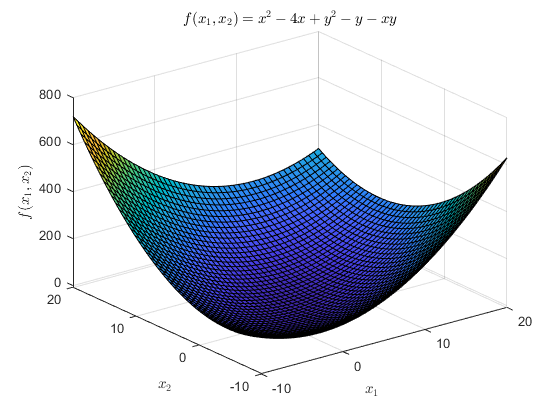

clear variablse;
clc;

f = @(x, y) x.^2 - 4 * x + y.^2 - y - x .* y;
x = linspace(-10, 20, 50);
y = linspace(-10, 20, 50);
[X, Y] = meshgrid(x, y);
Z = f(X, Y);
surf(X, Y, Z);
title('$f(x_1, x_2) = x^2 - 4 x + y^2 - y - x y$', 'interpreter', 'latex');
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'interpreter', 'latex');
zlabel('$f(x_1, x_2)$', 'interpreter', 'latex');


EPSILON = 1e-3;
% MAX_NUMBER_OF_ITERATIONS = 10000;
MAX_NUMBER_OF_ITERATIONS = 10000;
f = @(x) x(1).^2 - 4 * x(1) + x(2).^2 - x(2) - x(1) .* x(2);
%ALPHA = 2;
ALPHA = 1

ALPHA = 1

BETA = 0.5

BETA = 0.5000

%GAMMA = 5 / 2;
GAMMA = 2

GAMMA = 2

%X_0 = [0; 0]
X_0 = [0.5; 0.2]

X_0 =     0.5000
    0.2000


[x, numberofiterations] = neldermeadalgorithm(true, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS);

#:                      [0]
x_b:                    [5.14238345 2.05695338]
x_g:                    [0.50000000 0.20000000]
x_w:                    [7.92781353 3.17112541]
y_b:                    [-2.52896543]
y_g:                    [-2.01000000]
y_w:                    [12.88379324]
diff:                   [-10.35482781]
contract
#:                      [1]
x_b:                    [5.14238345 2.05695338]
x_g:                    [0.50000000 0.20000000]
x_w:                    [5.37450263 2.14980105]
y_b:                    [-2.52896543]
y_g:                    [-2.01000000]
y_w:                    [-1.69499991]
diff:                   [0.83396552]
contract
#:                      [2]
x_b:                    [4.09784718 1.63913887]
x_g:                    [5.14238345 2.05695338]
x_w:                    [0.50000000 0.20000000]
y_b:                    [-5.26834045]
y_g:                    [-2.52896543]
y_w:                    [-2.01000000]
diff:                   [3.25834045]
contract
#:

disp(['x:                    [', num2str(x', '%.8f '), ']']);

x:                    [2.90331501 1.16132600]


disp(['number of iterations: ', num2str(numberofiterations)]);

number of iterations: 15


function [x, numberofiterations] = neldermeadalgorithm(MINIMIZE, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS)
    % best result ca 2.2, 2.2 (Z = -6)
    x_0 = X_0;
    numberofiterations = -1;
    MIN_NUMBER_OF_ITERATIONS = 0;
    n = 2; % Anzahl Veränderlichen
    h = [3; 5; 8];
        
    x_list = createXVectorsForTriangle(n, x_0, h);
    [x_b, x_g, x_w] = defineTriangle(f, x_list, MINIMIZE);
    
    for i=0:MAX_NUMBER_OF_ITERATIONS
        
        y_w = f(x_w);
        y_g = f(x_g);                             
        y_b = f(x_b);
        
        diff = abs(y_b) - abs(y_w); % calculate diff between best and good for comp with epsilion
        
        if numberofiterations > MIN_NUMBER_OF_ITERATIONS && diff < EPSILON
            x = x_b;
            return;
        end
        
        numberofiterations = numberofiterations + 1;
        disp(['#:                      [', num2str(numberofiterations', '%.0f '), ']']);
        disp(['x_b:                    [', num2str(x_b', '%.8f '), ']']);
        disp(['x_g:                    [', num2str(x_g', '%.8f '), ']']);
        disp(['x_w:                    [', num2str(x_w', '%.8f '), ']']); 
        disp(['y_b:                    [', num2str(y_b', '%.8f '), ']']);
        disp(['y_g:                    [', num2str(y_g', '%.8f '), ']']);
        disp(['y_w:                    [', num2str(y_w', '%.8f '), ']']); 
        disp(['diff:                   [', num2str(diff', '%.8f '), ']']); 
        
        x_m = (x_b + x_g) / 2;
        x_r = (2 * x_m)- x_w;
        y_r = f(x_r);
     
        if isBetterThan(y_r, y_g, MINIMIZE)
            if isBetterThan(y_b, y_r, MINIMIZE)
                % reflect
                disp('reflect');
                x_w = x_r;
            else
                % extend
                disp('extend');
                x_e = (2 * x_r) - x_m;
                y_e = f(x_e);
                
                if isBetterThan(y_e, y_b, MINIMIZE)
                    x_w = x_e;
                else 
                    x_w = x_r;
                end                
            end
        else 
            if isBetterThan(y_r, y_w, MINIMIZE)
                x_w = x_r;
                continue;
            end
            
            %Contract
            disp('contract');
            x_c1 = (x_w + x_m) / 2;
            x_c2 = (x_r + x_m) / 2;
            
            y_c1 = f(x_c1);
            y_c2 = f(x_c2);           
            
            if isBetterThan(y_c1, y_c2, MINIMIZE)
                x_c = x_c1;
                y_c = y_c1;
            else 
                x_c = x_c2;
                y_c = y_c2;
            end
            
            if isBetterThan(y_c, y_w, MINIMIZE)
                x_w = x_c;
            else 
                %shrink
                disp('shrink');
                x_s = (x_w - x_b) / 2;                 
                x_g = x_m;
                x_w = x_s;
            end
        end
        
       
        %define new best, goods and worst values with the adjusted triangle        
        [x_b, x_g, x_w] = defineTriangle(f, [x_b, x_g, x_w], MINIMIZE);              
    end
    x = nan;
end

function [x_b, x_g, x_w] = defineTriangle(f, x_list, MINIMIZE)
    sz = size(x_list);
    len = sz(2);
    y_list = zeros(1,len);
    
    for i=1:len
        x_value = x_list(:, i);
        y_list(i) = f(x_value);
    end
    
    if MINIMIZE
        [~, indexes] = mink(y_list, 2);
        [~, i_w] = max(y_list);
        
        i_b = indexes(1);
        i_g = indexes(2);
    else
        [~, indexes] = maxk(y_list, 2);
        [~, i_w] = min(y_list);
        
        i_b = indexes(1);
        i_g = indexes(2);
    end
    
    x_b = x_list(:, i_b);
    x_g = x_list(:, i_g);
    x_w = x_list(:, i_w);          
end

function [x_list] = createXVectorsForTriangle(n, x, h)
    x_list = zeros(2, n+1);
    x_list(:, 1) = x;
    for i = 2:n+1        
        x_mi = x_list(:, i-1);
        x_i = x + h(i) * (x_mi)/norm(x_mi);
        x_list(:, i) = x_i;
    end
end

function better = isBetterThan(y1, y2, MINIMIZE)
    if MINIMIZE
        if y1 < y2
            better = true;
            return;
        end
        better = false;
        return;
    else 
        if y1 > y2
            better = true;
            return;
        end
        better = false; 
        return;
    end
end